# Matlab Project Assignment

# Task #02

## 1. Estimation using linear model

We observe two samples of a DC level A in correlated zero-mean Gaussian noise


$$\begin{array}{l}
x\left\lbrack 0\right\rbrack =A+w\left\lbrack 0\right\rbrack \\
x\left\lbrack 1\right\rbrack =A+w\left\lbrack 1\right\rbrack 
\end{array}$$


where $W={\left\lbrack \begin{array}{c}
w\left\lbrack 0\right\rbrack \;w\left\lbrack 1\right\rbrack 
\end{array}\right\rbrack }^T$ is zero-mean Gaussian random vector with covariance matrix $C=\sigma^2 \left\lbrack \begin{array}{cc}
1 & \rho \\
\rho  & 1
\end{array}\right\rbrack$.

### a. Finding the efficient estimator for A using the linear model

### b. Creating a Monte-Carlo simulation program for the problem using different values of $\rho$.


$$\rho =\left\lbrace -1,0,0\ldotp 5,1\right\rbrace$$
 

Including: -Table showing simulated variance and theoretical variance for each these values of $\rho$. 

                 -Table showing simulated mean and theoretical mean for each value of $\rho$.

close all ; clear ; clc ;
rng(0) ; % reset the random number generator (for reproducibility)

A = 2 ;
sigma_squared = 0.5 ;
MC = 100000 ; % number of Monte Carlo loops

rho = [-1, 0, 0.5, 1] ; % the values of rho to test for

N = 2 ; % Number of samples in the data
n = [0:N-1] ; % row vector to represent the index of each sample
H =  ones(N,1) ; % transformation matrix as derived in part 1.a


% intializing the results vectors
estimate_simulated = NaN*ones(size(rho)) ;
var_estimate_simulated = NaN*ones(size(rho)) ;
var_estimate_theory = NaN*ones(size(rho)) ;
estimate = cell(size(rho)) ;

for ii = 1:length(rho)
    %     all_C{ii} = sigma_squared.*[ 1 rho(ii) ; rho(ii) 1 ] ; % used to store C
    %     all_inv_C{ii} = inv(all_C{ii}) ; % used to store inverse of C

    C = sigma_squared.*[ 1 rho(ii) ; rho(ii) 1 ] ; % generate the covariance matrix

    noise = zeros(MC,N) + randn(MC,N)*chol(C) ; % W ==> N columns of GN with zero mean and C covariance matrix repeated MC rows
    %     cov_noise{ii} = cov(noise) ; % to check the cov of the noise (yes, it matches C)

    signal = H*A ; % H*A ==> linear model of the signal of interset
    X = signal + noise' ; % captured samples with MC times in columns and has N=2 samples in rows

    if det(C) ~= 0
        estimate{ii} = inv(H.'*inv(C)*H)*H.'*inv(C)*X ;  %  (from part 1.a) it gives 1*MC estimated values
        estimate_simulated(ii) = mean(estimate{ii}) ; % mean of the estimate along MC loops
        var_estimate_simulated(ii) = var(estimate{ii}) ;  % variance of the estimate along MC loops
        var_estimate_theory(ii) = inv(H.'*inv(C)*H) ; % from part 1.a
    else
%         estimate{ii} = inv(H'*H)*H'*X ;  %  LSE
        estimate{ii} = mean(X) ;  %  (mean along rows == along samples) it gives 1*MC estimated values
        estimate_simulated(ii) = mean(estimate{ii}) ; % mean of the estimate along MC loops
        var_estimate_simulated(ii) = var(estimate{ii}) ;  % variance of the estimate along MC loops
        var_estimate_theory(ii) = nan ;
    end
end
% all_C{:}
% all_inv_C{:}

results_est_mean = [estimate_simulated]

results_est_mean =     2.0000    1.9998    2.0017    2.0031


results_est_var = [var_estimate_simulated ; var_estimate_theory]

results_est_var =     0.0000    0.2505    0.3738    0.5001
       NaN    0.2500    0.3750       NaN



% latex(sym(results_est_mean))
% latex(sym(results_est_var))

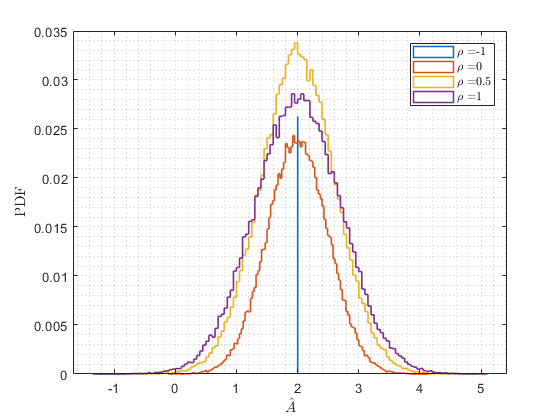

% Plotting thing
f1 = figure ;

for ii = 1:length(rho)
    histogram(estimate{ii},'Normalization','probability','DisplayStyle',"stairs",'LineWidth',1.2) ;
    hold on
    myLegend{ii} = strcat('$\rho =$', num2str(rho(ii))) ;
end
legend(myLegend,'interpreter','latex','Location','best') ;
grid minor
xlabel('$\hat{A}$','interpreter','latex') ;
ylabel('PDF','interpreter','latex') ;

exportgraphics(f1,'plot_Q1.pdf')

### c. What is special about plot with $\rho =-1$? why is it like this? Handle this value also properly in simulations.

## 2.Maximum likelihood estimator

### a. Find the maximum likelihood estimator of $\theta$

### b. Implement the maximum likelihood estimator for θ in MATLAB

### c. Implement also the following the estimator A_est_mean = samplemean ∗ 2 in MATLAB

### d.1.  Find out the fully theoretical PDF for both estimators

### d.2. Plot against simulated PDFs/histograms (all in the same figure)

close all ; clear ; clc ;
rng ; % reset the random number generator (so that we get the same results everytime)

MC = 100000 ; % number of Monte Carlo loops
theta = 1 ;
N = 100 ;

X = theta.*rand(N,MC) ; % N rows of uniform random elements repeated MC columns
% size(X)

theta_ML = max(X) ;  %  (from part 1.a) it gives MC*1 estimated values (max of X along the rows)
% size(theta_ML)

A_est_mean = 2*mean(X) ; % it gives MC*1 est_A values (2*sampleMean of X along the rows)
% size(A_est_mean)



% bias
if abs(mean(theta_ML) - theta)/abs(theta) < 0.01
    disp('ML estimator is unbiased')
else
    disp('ML estimator is biased')
end

ML estimator is unbiased



if abs(mean(A_est_mean) - theta)/abs(theta) < 0.01
    disp('A_est_mean is unbiased')
else
    disp('A_est_mean is biased')
end

A_est_mean is unbiased


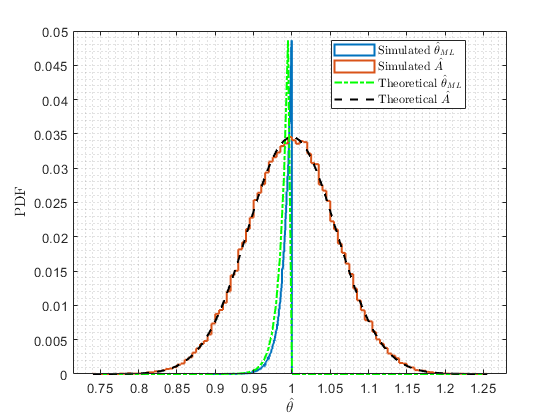

f2 = figure ;

H1 = histogram(theta_ML,'Normalization','probability','DisplayStyle',"stairs",'LineWidth',1.5) ;
hold on
H2 = histogram(A_est_mean,'Normalization','probability','DisplayStyle',"stairs",'LineWidth',1.5) ;
hold on

X2 = linspace(H2.BinLimits(1),H2.BinLimits(2),100) ; % range of x for theoretical results

ML_theor_PDF = betapdf(X2,N,1) ;
ML_theor_PDF_normalized = normalize(ML_theor_PDF, ...
    'range',[min(H1.Values(:)) max(H1.Values(:))]) ;
plot(X2, ML_theor_PDF_normalized,'g-.','Linewidth',1.5) ;

A_est_mean_theor_PDF = normpdf(X2,theta,sqrt((theta)^2/(3*N))) ;
A_est_mean_theor_PDF_normalized = normalize(A_est_mean_theor_PDF, ...
    'range',[min(H2.Values(:)) max(H2.Values(:))]) ;
plot(X2, A_est_mean_theor_PDF_normalized,'k--','Linewidth',1.5) ;

% xline(theta,'y--','Linewidth',1) ;

grid minor
legend('Simulated $\hat{\theta}_{ML}$','Simulated $\hat{A}$','Theoretical $\hat{\theta}_{ML}$', ...
    'Theoretical $\hat{A}$ ','interpreter','latex','Location','best') ; 
xlabel('$\hat{\theta}$','interpreter','latex') ;
ylabel('PDF','interpreter','latex') ;

exportgraphics(f2,'plot_Q2.pdf')